Ejemplo de diseño de filtro digital

autor: Filipuzzi, Fernando Rafael

versión: 20230314

Matlab:2022b

function [B,A]=mi_fir1(varargin)

% N, W, VENTANA
% number of arguments check
narginchk(2,4);
N=double(varargin{1});
Wn=double(varargin{2});
TIPO="paso bajo"; 
if nargin>=3
    TIPO=varargin{3};
end
VENTANA="rectangular";
if nargin>=4
    VENTANA=varargin{4};
end

            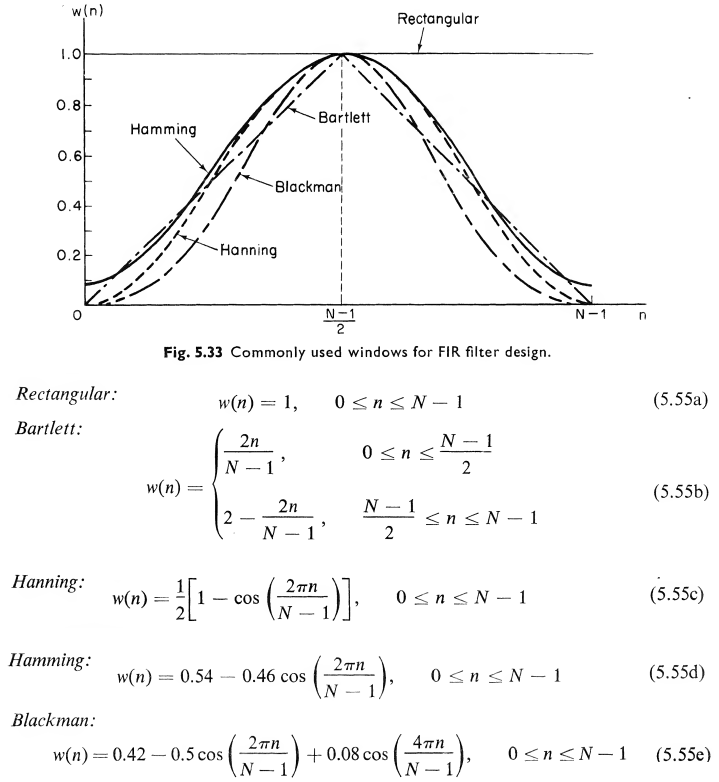

    
    a= (N-1)/2;
    

    %selección de la ventana
    w = @(m) 1;
    switch VENTANA
        case "rectangular"
            w = @(m) 1;
        case "hanning"
            w = @(m) 1/2*[1-cos(2*pi*m/(N-1))];
        case "hamming"
            w = @(m) 0.54 - 0.46*cos(2*pi*m/(N-1));
        case "blackman"
            w = @(m) 0.42 - 0.5*cos(2*pi*m/(N-1))- 0.08*cos(4*pi*m/(N-1));            
    end

[dietrich]       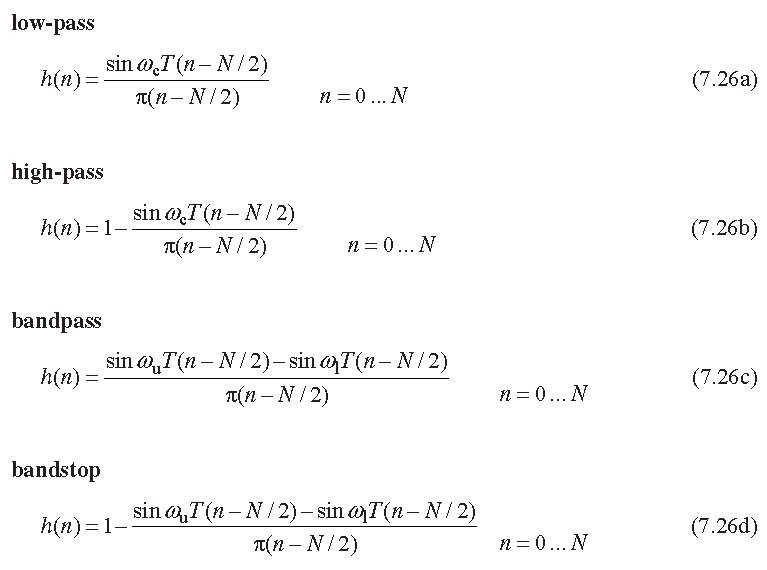

    
    Wn=Wn(end);
    % hn = @(m) (m~=0).*((sin(pi*Wn*(m) )./( pi*(m) )) + (sin(pi*Wn*(m) )./( pi*(m))+ (m==a).*Wn;         
    %

    

    %
    h = hn(0:N-1,Wn,N);

    %
    A=1;
    B=h.*w(0:N-1);

end



function [y]=hn(n,Wn,N)

    hn1 = @(m) sin(pi*Wn*(m) )./( pi*(m) );
    
    if(n~=0 && n~=(N-1))
        y=hn1(m-0)+hn1(m-N+1);
    else
        y=Wn;
    end
end